%BPA 多点目标单站 SAR
% 这个代码只成了一个条带的像
%parametcrs from Table 6,1
%date: 2010/10/14
clc;
clear all;
close all;

## 参数定义

%=========================================
c=3e8;
j=sqrt(-1);
pi=3.1416;

fc=5.3e9;   
lamda=c/fc;
D=4;                          % 方位向天线尺寸
Va=150;                       % 等效雷达速度
Kr=20e12;                     % 距离调频率
Tr=2.5e-6;                    % 发射脉冲时宽
sq_ang=3.5/180*pi;            % 波束斜视角 （增大波束斜视角，方向维合成孔径长度增加） 

Br=Kr*Tr;                     % 带宽
Frfactor=1.2;                 % 距离向过采样率
Fr=Br*Frfactor;               % 距离向采样频率
Ba=0.886*2*Va*cos(sq_ang)/D;  % 多普勒带宽 
Fafactor=1.2;                 % 方位向过采样率
Fa=Ba*Fafactor;               % 方位向采样频率

R_near=2e4;                   % 场景近端(零多普勒位置斜距)
R_far=R_near+1000;            % 场景远端(零多普勒位置斜距)


La_near=0.886*R_near*lamda/(cos(sq_ang).^2)/D;    % 场景近端合成孔径长度            
La_far=0.886*R_far*lamda/(cos(sq_ang).^2)/D;      % 场景远端合成孔径长度  为啥有平方画个图你就知道了，第一个cos因为斜视，目标离雷达的距离变远需要除以一个cos，第二个cos是由于几何关系产生的，因为斜视之后长度不能直接用半径乘以角度得到，而应该在此的基础上再除以一个cos
Tc_near=-R_near*tan(sq_ang)/Va;              % 场景近端波束中心穿过时间(以零多普勒位置为参考时间)
Tc_far=-R_far*tan(sq_ang)/Va;                % 场景远端波束中心穿过时间(以零多普勒位置为参考时间)
fdc=2*Va*sin(sq_ang)/lamda;                  % 多普勒中心频率


Rmin=sqrt(R_near^2+(Tc_near*Va+La_near/2)^2);  % 雷达和该条带的最短斜距           
Rmax=sqrt(R_far^2+(Tc_far*Va-La_far/2)^2);     % 雷达和该条带的最远斜距          



disp('参数');

参数


disp('雷达的实波束宽度');disp(0.886*lamda/D);

雷达的实波束宽度
    0.0125



disp('雷达的斜视角');disp(sq_ang/pi*180);

雷达的斜视角
    3.5000



disp('雷达和场景间的最短斜距:');disp(Rmin);

雷达和场景间的最短斜距:
   2.0030e+04



disp('雷达和场景间的最远斜距:');disp(Rmax);

雷达和场景间的最远斜距:
   2.1048e+04



disp('距离分辨率:');disp(0.886*(c/2/Br));

距离分辨率:
    2.6580



disp('方位分辨率:');disp(0.886*Va/Ba);                 %??????????????????????????????

方位分辨率:
    2.0037



disp('多普勒中心:');disp(fdc);

多普勒中心:
  323.5580



## 回波模型

%====================================================
Nr=(2*Rmax/c+Tr-2*Rmin/c)*Fr;
Nr=2^nextpow2(Nr);                                       % 距离向采样点数
tr=linspace(-Tr/2+2*Rmin/c,Tr/2+2*Rmax/c,Nr);            % 距离向采样时间(以每个发射脉冲时刻为参考时间)        为什么要这样？
Fr=(Nr-1)/(Tr/2+2*Rmax/c-(-Tr/2+2*Rmin/c));              % 距离向采样频率
Na=((Tc_near+La_near/2/Va)-(Tc_far-La_far/2/Va))*Fa;
Na=2^nextpow2(Na);                                       % 方位向采样点数
ta=linspace(Tc_far-La_far/2/Va,Tc_near+La_near/2/Va,Na); % 方位向采样时间(以零多普勒位置为参考时间)
Fa=(Na-1)/(Tc_near+La_near/2/Va-(Tc_far-La_far/2/Va));   % 方位向采样频率

disp('由方向维采样频率限制的雷达与场景任意一点的最远斜距：');disp(1/Fa*c/2);

由方向维采样频率限制的雷达与场景任意一点的最远斜距：
   1.2516e+06




Rpt=[R_near R_near R_near+1000 R_near+1000];                     % 点目标位置(斜距)
Ypt=[10 -10 10 -10];
Npt=length(Rpt);                                         % 目标数目
La=0.886*Rpt*lamda/(cos(sq_ang))/D;                      % 每个目标的合成孔径长度
Tc=-Rpt*tan(sq_ang)/Va;                                  % 每个目标的波束中心时间
                               

Y_high=max(Ypt)+50;      % 确定成像网格的范围，以使其包括目标点；
Y_low=min(Ypt)-50;       % 成像区域是（R_right-R_left) *(Y_high-Y_low) 的一片区域
R_left=R_near-50;
R_right=R_far+50;

disp('点目标数量:');disp(Npt);

点目标数量:
     4



disp('距离维采样点数:');disp(Nr);

距离维采样点数:
        1024



disp('方向维采样点数:');disp(Na);

方向维采样点数:
   256



disp('距离维采样频率:');disp(Fr);

距离维采样频率:
   1.1019e+08



disp('方向维采样频率:');disp(Fa);

方向维采样频率:
  119.8504



disp('最小合成孔径长度:');disp(0.886*R_near*lamda/(cos(sq_ang))/D);

最小合成孔径长度:
  251.2233



disp('最大合成孔径长度:');disp(0.886*(R_near+1000)*lamda/(cos(sq_ang))/D);

最大合成孔径长度:
  263.7845



disp('雷达移动范围');disp((Tc_near+La_near/2/Va)-(Tc_far-La_far/2/Va)*Va);

雷达移动范围
   1.4092e+03



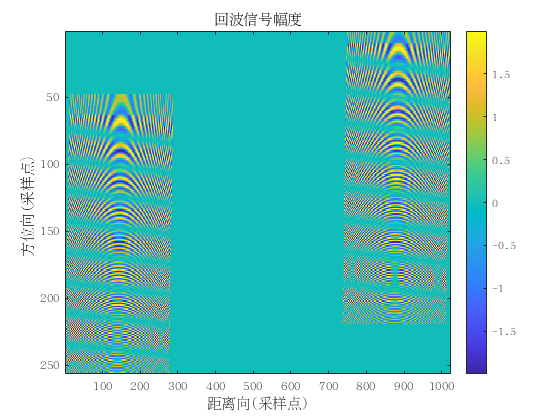


sig=zeros(Na,Nr);
for k=1:Npt
	delay=2/c*sqrt(Rpt(k)^2+(Ypt(k)-ta*Va).^2);                            % 点目标到雷达每个方位点距的时延
	Dr=ones(Na,1)*tr-delay'*ones(1,Nr);                                   
	sig=sig+exp(j*pi*Kr*Dr.^2-j*2*pi*fc*delay'*ones(1,Nr))...              % 基带回波信号，第一个相位项为线性调频产生的相位，第二个相位项为距离实验产生的相位
            .*(abs((ta-(Tc(k)+Ypt(k)/Va))'*ones(1,Nr))<=La(k)/2/Va)...     % <= 号限制取值范围; 方向维采样时刻与目标多普勒中心时刻的时间差应该小于该目标点孔径时间的一半
            .*(abs(Dr)<=Tr/2);                                             % 由这个可以知道为啥匹配滤波压缩后的结果是中间，因为它一开始就在中间
end

figure('Name','回波信号幅度');imagesc(real(sig)) ;
colorbar
title('回波信号幅度');xlabel('距离向(采样点)');ylabel('方位向(采样点）'); 

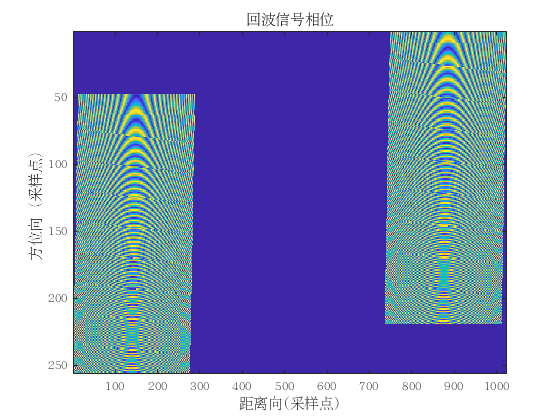

figure('Name','回波信号相位'); imagesc(abs(angle(sig)));
title('回波信号相位');xlabel('距离向(采样点)');ylabel('方位向（采样点）'); 

%==============================================================

## BP 算法

## 步骤一：距离向匹配滤波

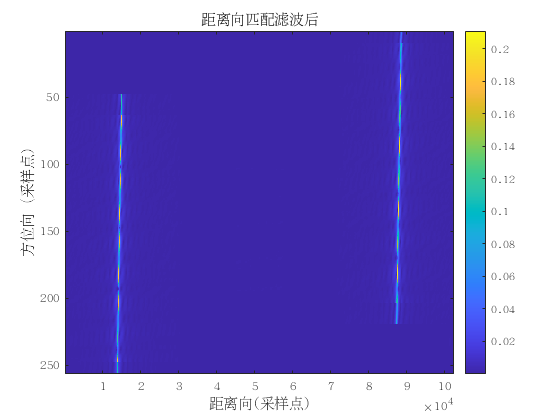

sig_rd=fft(sig,[],2);
fr=-1/2:1/Nr:(1/2-1/Nr);
fr=fftshift(fr*Fr);
%  fr=0:Fr/Nr:(Fr/2-Fr/Nr);
filter_r=ones(Na,1)*exp(j*pi*fr.^2/Kr);      %从0到tau的门函数傅里叶变换的相频特性经过原点
sig_rd=sig_rd.*filter_r;
nup=100;                           % 距离向升采样系数为100
Nr_up=Nr*nup;                      % 生采样之后的频域采样个数
nz=Nr_up-Nr;                       % 需要补零的个数
dtr=1/nup/Fr;                      % 补零之后的时域分辨率
sig_rd_up=zeros(Na,Nr_up);
sig_rd_up=[sig_rd(:,1:Nr/2),zeros(Na,nz),sig_rd(:,(Nr/2+1):Nr)];
sig_rdt=ifft(sig_rd_up,[],2);
figure('Name','距离向匹配滤波后');imagesc(abs(sig_rdt));colorbar
title('距离向匹配滤波后');xlabel ('距离向(采样点)');ylabel('方位向（采样点)');

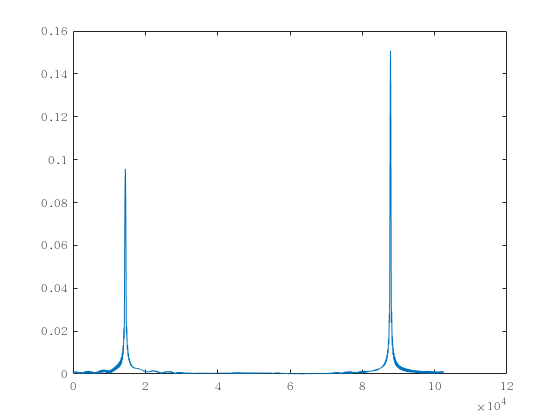

figure('Name','方位第128个采样点的信号');plot(abs(sig_rdt(128,:)));

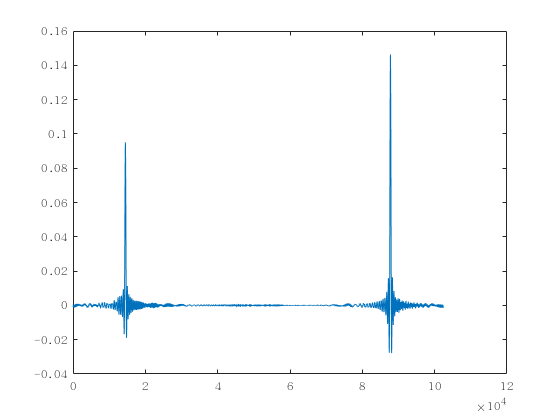

figure('Name','方位第128个采样点的信号');plot(real(sig_rdt(128,:)));

## 步骤二 对成像区域进行网格化（Na*Nr)

R=zeros(1,Nr);
for ii=1:Nr
%   R(1,ii)=R_near+(R_far-R_near)/(Nr-1)*(ii-1);
    R(1,ii)=R_left+(R_right-R_left)/(Nr-1)*(ii-1);
end
Y=zeros(1,Na);
for ii=1:Na
	Y(1,ii)=Y_low+(Y_high-Y_low)/(Na-1)*(ii-1);
end


R=ones(Na,1)*R;
Y=Y'*ones(1,Nr);

## 步骤三：根据时延在回波域寻找相应位置并进行成像

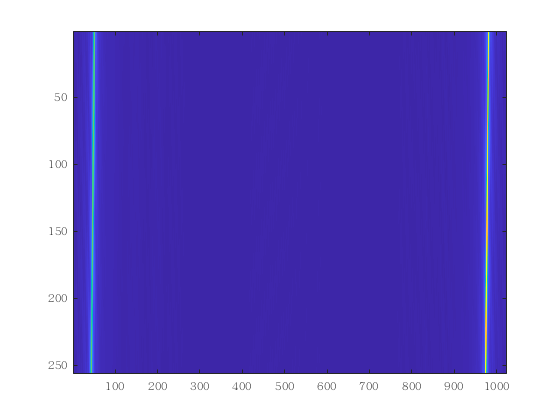

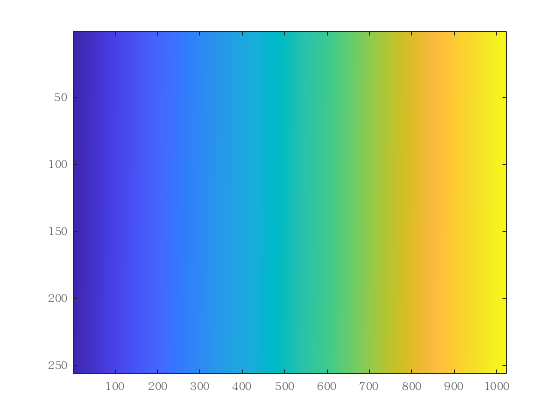

f_back=zeros(Na,Nr) ;
m_back = zeros(Na,Nr);
gridpoint = zeros(Na,Nr);

for ii=1:Na
%ii=100;
	R_ij=sqrt(R.^2+(Y-Va*ta(ii)).^2);  % 每个网格对于每一雷达位置的距离
	t_ij=2*R_ij/c;                     % 每个网格对于每一雷达位置的时延
    t_ij=round((t_ij-(2*Rmin/c-Tr/2))/dtr);   % 每个网格点相对于距离采样起始时刻的采样位置
    
    
 	it_ij=(t_ij>0&t_ij<=Nr_up);
 	t_ij=t_ij.*it_ij+Nr_up*(1-it_ij); %% 将矩阵中为零的元素用Nr_up代替
 
	sig_rdta=sig_rdt(ii,:);
%     figure('Name','方位第个采样点的信号');plot(abs(sig_rdta));
    
	sig_rdta(Nr_up)=0;
    if ii == 128
    gridpoint = abs(sig_rdta(t_ij));
    figure;
    imagesc(gridpoint);
    figure;
    imagesc(t_ij);
    end
    
	f_back=f_back+sig_rdta(t_ij).*exp(1i*4*pi*R_ij/lamda);  
    m_back = m_back + abs(sig_rdta(t_ij));
%   f_back=f_back+abs(abs(sig_rdta(t_ij)));
   

end

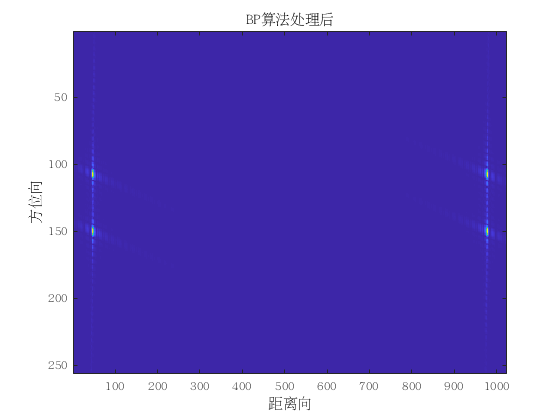



figure('Name','BP算法处理后，使用相位校正'); imagesc(abs(f_back));
title('BP算法处理后');xlabel('距离向'); ylabel('方位向');

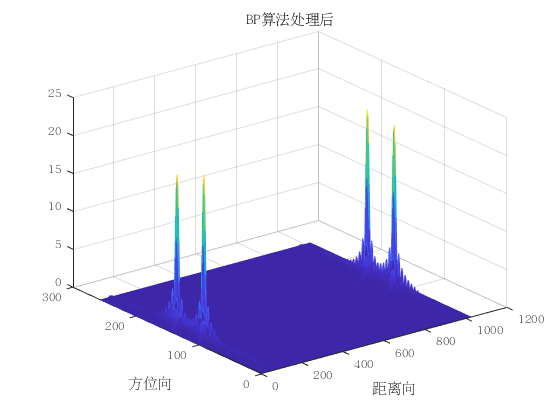

figure('Name','BP算法处理后，使用绝对值相加处理'); mesh(abs(f_back));
title('BP算法处理后');xlabel('距离向'); ylabel('方位向');

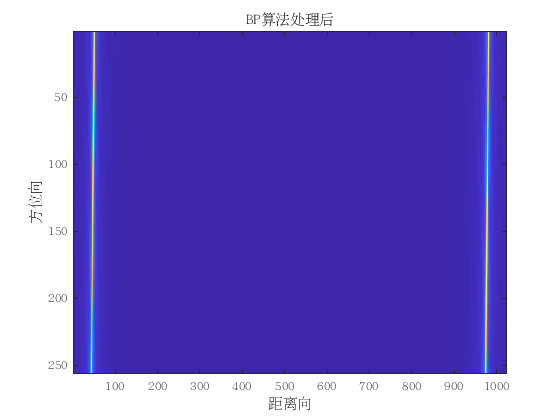


figure('Name','BP算法处理后，使用绝对值相加处理'); imagesc(abs(m_back));
title('BP算法处理后');xlabel('距离向'); ylabel('方位向');

% 使用绝对值相加处理，效果不好，原因可能是对于压缩后的sinc函数，主峰上临近
% 的两点，他们的绝对值相近，而相位相差很远


% figure('Name','BP算法处理后'); imagesc(abs(m_back));
% title('BP算法处理后');xlabel('距离向'); ylabel('方位向');